clc;
clear;

% Robot parameters
d1 = 3;
L1 = 10;
L2 = 10;
L3 = 3;

% Define all sets of theta values
theta_set1 = [0, 30, -60, 60, 0];
theta_set2 = [60, 60, -20, 50, 0];
theta_set3 = [130, 30, -10, 40, 0];
theta_set4 = [220, 50, -10, 30, 0];
theta_set5 = [310, 45, 0, 45, 0];
theta_sets = [theta_set1; theta_set2; theta_set3; theta_set4; theta_set5];

% Convert to radians
theta_sets_rad = deg2rad(theta_sets);
IK_theta_sets = zeros(size(theta_sets_rad, 1), 5);
IK_position_sets = zeros(size(theta_sets_rad, 1), 5);
% Loop through each set
for i = 1:size(theta_sets_rad, 1)
    
    theta_sol = theta_sets_rad(i, :);

    % Forward kinematics
    psi = theta_sol(2) + theta_sol(3) + theta_sol(4);
    u = theta_sol(5);
    T01 = DistalDH([0, pi/2, d1, theta_sol(1)]);
    T12 = DistalDH([L1, 0, 0, theta_sol(2)]);
    T23 = DistalDH([L2, 0, 0, theta_sol(3)]);
    T34 = DistalDH([0, pi/2, 0, theta_sol(4)]);
    T45 = DistalDH([0, 0, L3, theta_sol(5)]);
    T05 = T01 * T12 * T23 * T34 * T45;

    % Extract position from forward kinematics
    xw = T05(1,4);
    yw = T05(2,4);
    zw = T05(3,4);

    % Call inverse kinematics
    [theta1, theta2, theta3, theta4, theta5] = inverse_kinematics(xw, yw, zw, psi, d1, L1, L2, L3, theta_sol(1), theta_sol(5));

    % Convert results to degrees and display
    t1 = round(rad2deg(theta1), 3);
    t2 = round(rad2deg(theta2), 3);
    t3 = round(rad2deg(-theta3), 3);
    t4 = round(rad2deg(theta4), 3);
    t5 = round(rad2deg(theta5), 3);
    
    IK_theta_sets(i, :) = [t1, t2, t3, t4, t5];
    IK_position_sets(i, :) = [xw, yw, zw, psi, u];
end

fprintf('Initial theta sets: ');

Initial theta sets: 

disp(theta_sets);

     0    30   -60    60     0
    60    60   -20    50     0
   130    30   -10    40     0
   220    50   -10    30     0
   310    45     0    45     0



fprintf('IK theta sets: ');

IK theta sets: 

disp(IK_theta_sets);

     0    30   -60    60     0
    60    60   -20    50     0
   130    30   -10    40     0
  -140    50   -10    30     0
   -50    45     0    45     0



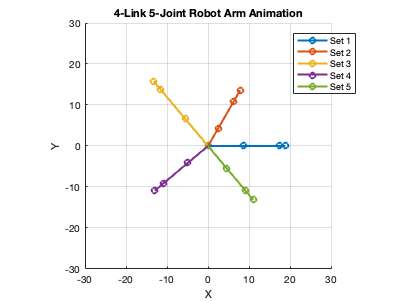


figure;
hold on;
grid on;
axis equal;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('4-Link 5-Joint Robot Arm Animation');
xlim([-30, 30]);
ylim([-30, 30]);
zlim([0, 30]);

for i = 1:size(IK_theta_sets, 1)
    theta = IK_theta_sets(i, :);
    joint_positions = Calc_JointPos(theta);
    
    % plot
    plot3(joint_positions(:,1), joint_positions(:,2), joint_positions(:,3), '-o', ...
          'LineWidth', 2, 'MarkerSize', 6);
    pause(1); 
end

legend show;
legend({'Set 1', ...
        'Set 2', ...
        'Set 3', ...
        'Set 4', ...
        'Set 5'}, ...
        'Location', 'best');
hold off;


t = 1:size(IK_position_sets, 1);  % Time steps
tt = linspace(1, size(IK_position_sets, 1), 100);  % Sample more points
spline_path = spline(t, IK_position_sets', tt);  % Cubic spline interpolation

